IdMPL = 7;
Id2TA = 1;

load(myProject.FeaturesLists{IdMPL}.Original.Name);

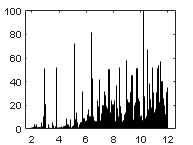

PeakList = myMrgPeakList.PeakList;
ThrArea = prctile(PeakList.chrom_area, 75);
step = 0.02;
axisX = min(PeakList.chrom_Time_IA)-3*step:step:max(PeakList.chrom_Time_IA)+3*step;
histogram(PeakList.chrom_Time_IA, axisX);

Area = myMrgPeakList.TargetedAnalysis{1, 1}.Area;
PeakList = myMrgPeakList.PeakList;
ThNoise = prctile(Area.Values(Area.Values > 0), 5, 'all');
% NoiseLvl =  mean(Area.Values(Area.Values > 0 & Area.Values < ThNoise)) + ...
%     2*std(Area.Values(Area.Values > 0 & Area.Values < ThNoise))
NoiseLvl =  mean(Area.Values(Area.Values > 0 & Area.Values < ThNoise));
ThreNum1 = [10, 106, 10];

IdSel1 =  Area.ID(sum(Area.Values >= 10*NoiseLvl, 2) >= 25);
[~, ~, IdSel1] = intersect(IdSel1, PeakList.ID);
firstPeakList = PeakList(IdSel1, :);
secondPeakList = PeakList;
secondPeakList(IdSel1, :) = [];

%% FIRST LOOP
ThMt = 0.02; % min
ThSim = 0.4;
ClustersSummary = [];
Cluster = {};
while 1
    vectorArea = [];
    firstPeakList = sortrows(firstPeakList,"chrom_intensity_apex","descend");
    if isempty(firstPeakList), break; end
    
    VectCC = (1:height(firstPeakList))';
    
    for ii = 1:height(firstPeakList)
        VectCC(ii, 2) = firstPeakList.chrom_Time_IA(ii);
        vectorArea(ii, :) = Area.Values(Area.ID == firstPeakList.ID(ii), :);

    end

    Id4Cl = find((abs(pdist2(vectorArea(1, :), vectorArea, 'correlation')) <= ThSim)' &  abs(VectCC(:, 2) - VectCC(1, 2)) < ThMt);
    mPL = firstPeakList(Id4Cl, :);
    Cluster{end+1}.SumArea = sum(vectorArea(Id4Cl, :), 1);
    Cluster{end}.Area = vectorArea(Id4Cl, :);

    if height(mPL) > 1
        Cluster{end}.Features = mPL;
        ClustersSummary(end+1, :) = [numel(Cluster), height(mPL), mean(mPL.chrom_Time_IA), std(mPL.chrom_Time_IA), mPL.ms_Accu_mass_1(1), mPL.chrom_area(1)];

    else
        ClustersSummary(end+1, :) = [numel(Cluster), height(mPL), mean(mPL.chrom_Time_IA), NaN, mPL.ms_Accu_mass_1(1), mPL.chrom_area(1)];
        Cluster{end}.Features = mPL;

    end
    firstPeakList(Id4Cl, :) = [];

end

ClustersSummary(:, 1) = (1:height(ClustersSummary))';

OptiMe = [];
for ii = 1:numel(Cluster)
    if height(Cluster{ii}.Features) == 1, continue; end

    OptiMe = [OptiMe; [(Cluster{ii}.Features.chrom_Time_IA - mean(Cluster{ii}.Features.chrom_Time_IA)) (pdist2(Cluster{ii}.SumArea, Cluster{ii}.Area, "correlation")')]];
end

SigmaTm = std(OptiMe(:,1))

SigmaTm = 0.0032

while 1
    stopMe = true;

    for ii = 1:numel(Cluster)
        IdMerge = find(abs(ClustersSummary(ii, 3) - ClustersSummary(:, 3)) < 6*SigmaTm);


        for jj = 1:numel(IdMerge)
            if ii == IdMerge(jj), continue; end

            if pdist2(Cluster{ii}.SumArea, Cluster{IdMerge(jj)}.SumArea, "correlation") <= ThSim
                stopMe = false;
                FullData = [Cluster{ii}.Features; Cluster{IdMerge(jj)}.Features];
                AllArea = [Cluster{ii}.Area; Cluster{IdMerge(jj)}.Area];
                [FullData, Index] = sortrows(FullData,"chrom_intensity_apex","descend");
                AllArea = AllArea(Index, :);

                Cluster{ii}.SumArea = sum(AllArea, 1);
                Cluster{ii}.Area = AllArea;
                Cluster{ii}.Features = FullData;
                ClustersSummary(ii, :) = [ii, height(FullData), mean(FullData.chrom_Time_IA), std(FullData.chrom_Time_IA), FullData.ms_Accu_mass_1(1), FullData.chrom_area(1)];
                Cluster(IdMerge(jj)) = [];
                ClustersSummary(IdMerge(jj), :) = [];
                break

            end
        end

        if ~stopMe, break; end
    end
    if stopMe, break; end


end

% for ii = 1:numel(Cluster)
%     IdAdd = find(abs(mean(Cluster{ii}.Features.chrom_Time_IA) - secondPeakList.chrom_Time_IA)/SigmaTm < 3);
%     if ~isempty(IdAdd)
%         Cluster{ii}.ExtraFeatures = secondPeakList(IdAdd, :);
%         ClustersSummary(ii, 7) = ClustersSummary(ii, 2) + numel(IdAdd);
% 
%     end
% end
% ClustersSummary(:, 1) = (1:height(ClustersSummary))';


ClustersSummary(:, 7) = ClustersSummary(:, 2);
for ii = 1:height(secondPeakList)
    Zlist = abs(ClustersSummary(:, 3) - secondPeakList.chrom_Time_IA(ii))/SigmaTm ;
    [MMinZ, IdZ] = min(Zlist);
    if MMinZ < 3
        if isfield(Cluster{IdZ}, 'ExtraFeatures')
            Cluster{IdZ}.ExtraFeatures = [Cluster{IdZ}.ExtraFeatures; secondPeakList(ii, :)];

        else
            Cluster{IdZ}.ExtraFeatures = secondPeakList(ii, :);

        end
        ClustersSummary(IdZ, 7) = ClustersSummary(IdZ, 7) + 1;
    end

end


SumCluster = {};
for ii = 1:numel(Cluster)
    cClust = Cluster{ii}.Features;
    mTm = mean(Cluster{ii}.Features.chrom_Time_IA);
    cClust.Similarity = pdist2(Cluster{ii}.SumArea, Cluster{ii}.Area, "correlation")';

    if isfield(Cluster{ii}, 'ExtraFeatures')
        eClust = Cluster{ii}.ExtraFeatures;
        eClust.Similarity = nan(height(eClust), 1);
        cClust = [cClust; eClust];

    end

    cClust = sortrows(cClust,"chrom_intensity_apex","descend");
    nClust = cClust(:, [10, 9, 15, 24]);
    nClust.Zdistance = (nClust.chrom_Time_IA - mean(nClust.chrom_Time_IA))/SigmaTm;
    SumCluster{ii} = nClust;
    CC = pdist2(Cluster{ii}.SumArea, Cluster{ii}.Area, "correlation");
    if numel(CC) < 2
        ClustersSummary(ii, 8) = NaN;

    else
        CC = sort(CC);
        ClustersSummary(ii, 8) = CC(2);

    end

end
ClustersSummary(:, 1) = (1:height(ClustersSummary))';
ClustersSummary(isnan(ClustersSummary(:, 8)), :) = [];


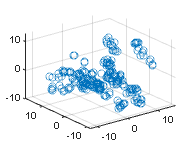

for ii = 1:height(ClustersSummary)
    Ar(ii, :) = Cluster{ClustersSummary(ii, 1)}.SumArea;

end

[wcoeff,score,latent,tsquared,explained] = pca(Ar','VariableWeights','variance');
figure
scatter3(score(:, 1), score(:, 2), score(:, 3));

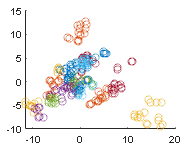

load('myMap.mat')

figure, hold on
for ii = 1:16
scatter3(score(myMap.Code == ii, 2), score(myMap.Code == ii, 3), score(myMap.Code == ii, 4));
end
hold off

writetable(SumCluster{ClustersSummary(1, 1)}, 'AllClusters.dat', "WriteRowNames",true)
for ii = 2:height(ClustersSummary)
    writelines("", 'AllClusters.dat',WriteMode="append")
    writetable(SumCluster{ClustersSummary(ii, 1)}, 'AllClusters.dat', "WriteRowNames",true,'WriteMode','Append')
end